"Alphacoronavirus.xlsx"

ans = "Alphacoronavirus.xlsx"

[~,f1] = xlsread(ans);
"Betacoronavirus.xlsx"

ans = "Betacoronavirus.xlsx"

[~,f2] = xlsread(ans);
"Deltacoronavirus.xlsx"

ans = "Deltacoronavirus.xlsx"

[~,f3] = xlsread(ans);

dc=20

dc = 20

f1 = f1(1:dc,2);
f2 = f2(1:dc,2);
f3 = f3(1:dc,2);

dim = 22;
a_m=[];
b_m=[];
c_m=[];

for i=1:dc
    f11=cell2mat(f1(i));
    f22=cell2mat(f2(i));
    f33=cell2mat(f3(i));
    a = cgrDft(f11);
    b = cgrDft(f22);
    c = cgrDft(f33);
    a_m =[a_m ; evenScaleVector(a,dim)];
    b_m =[b_m ; evenScaleVector(b,dim)];
    c_m =[c_m ; evenScaleVector(c,dim)];
end

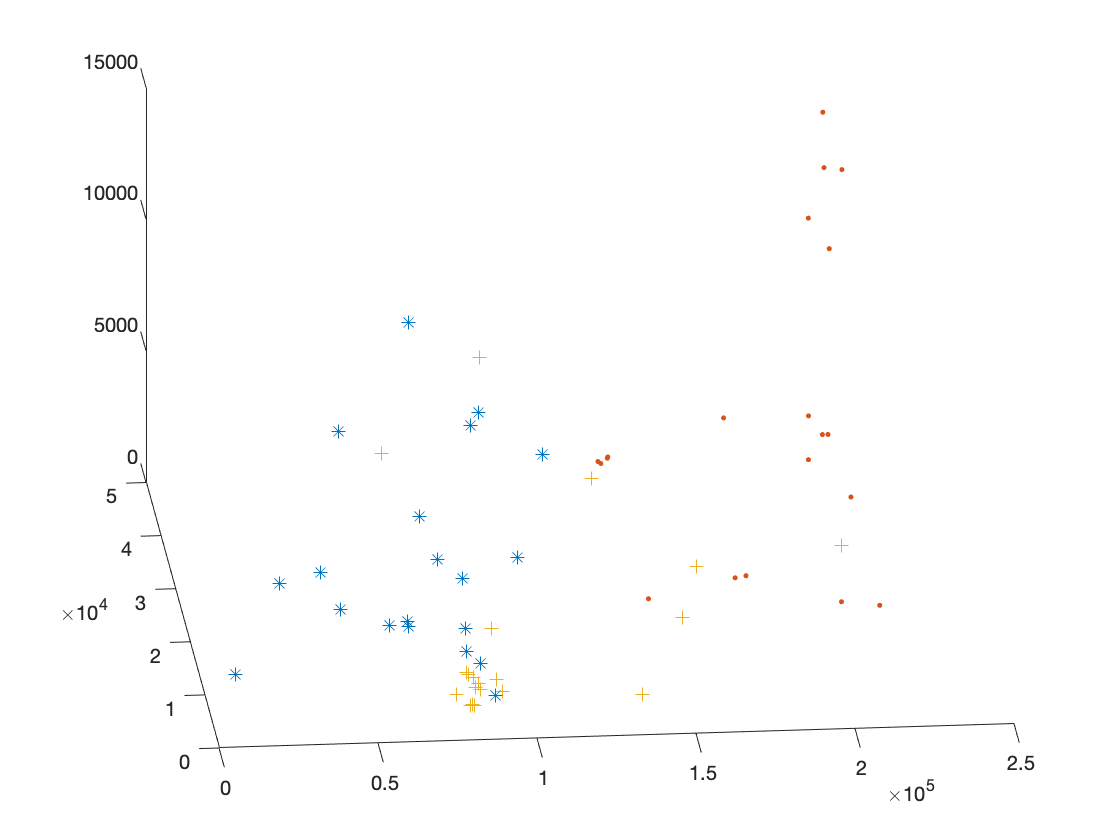

figure
plot3(a_m(:,1),a_m(:,2),a_m(:,3),'*')
hold on
plot3(b_m(:,1),b_m(:,2),b_m(:,3),'.')
hold on
plot3(c_m(:,1),c_m(:,2),c_m(:,3),'+')

function [ PSZ ] = cgrDft( seq )
len = length(seq);
x(1) = 0.0; y(1) = 0.0;
z(1) = x(1) + 1i * y(1);
for j = 1:len
    
    a = seq(j);
    
    switch a
    
    case 'A'
            v = [0,0];
    case 'C'
            v = [0,1];
    case 'G'
            v = [1,0];
    case 'T'
            v = [1,1];
    end
    
    x(j+1) = 0.5 * (x(j) + v(1));
    y(j+1) = 0.5 * (y(j) + v(2));
    z(j+1) = x(j+1) + 1i * y(j+1);  
end
%[x;y]'
 %figure;
% plot(x,y);
% scatter(x,y,'.');
 %xlim([0,1]);
 %ylim([0,1]);
%Discrete Fourier Transforms
Z = fft(z);
%Power spectrums
PSZ = abs(Z).^2;
PSZ(1)=[]; %Exclude the first term
end

function [Tm] = evenScaleVector(Tn,M)

 N = length(Tn);
 Tm = zeros(1,M);
 Tm(1) = Tn(1);
 
 for k = 2:M
   Q = k*N/M;
   R = floor(k*N/M);
  
   if R == 0
      R = 1;
   end
    
   if Q == R  %Q is an integer  
      Tm(k) = Tn(Q);
   else       %Q is not an integer  
      Tm(k) = Tn(R) + (Q-R)*(Tn(R+1)-Tn(R)); 
   end
end
end 
